%%%% ============= Node Wise Dissimilar Load Profile: PCA Spatial Data Reconstruction ============= %%%%

clear all
close all
clc

file='Data.xlsx';

% =================  Bus power data of IEEE 123 bus ================= %
% data1=xlsread(file,1); % Bus power data
% bus=data1(:,1);
% phA_kw=data1(:,2);
% phA_kVAR=data1(:,3);
% phB_kw=data1(:,4);
% phB_kVAR=data1(:,5);
% phC_kw=data1(:,6);
% phC_kVAR=data1(:,7);
% T_kw=data1(:,8);
% T_kVAR=data1(:,9);
% Nbus=max(bus);

bus_data=xlsread(file,8);% Bus power data
branch_data = xlsread(file,9)% Branch data

branch_data =     1.0000    2.0000    0.0000    0.0000
    2.0000    3.0000    0.0232    0.0475
    3.0000    4.0000    0.0441    0.0447
    3.0000    5.0000    0.0629    0.0638
    3.0000    9.0000    0.0174    0.0356
    5.0000    6.0000    0.0503    0.0510
    5.0000    7.0000    0.0818    0.0829
    7.0000    8.0000    0.0629    0.0638
    9.0000   10.0000    0.0116    0.0238
   10.0000   11.0000    0.0566    0.0574


bus=bus_data(:,1);
T_kw=bus_data(:,2);
T_kVAR=bus_data(:,3);
Nbus=max(bus);

% offline similar voltage data of IEEE 123 bus system
dissim_voltages = xlsread("all_bus_voltages_dissimilar_newest.csv");
dissim_data = dissim_voltages(2:end,2:end);
[cols,index] = sort(dissim_voltages(1,2:end));
sorted_dissim_voltages = dissim_data(:,index)'

sorted_dissim_voltages =     1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495
    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    


% ============ Sample load profile generation: 1-min ============== %
% T=96; 
T=24*60;

% % ==== Dissimilar Load Profile ====
data2=xlsread(file,5);
trainpu=data2(2:1441,2:126);
trainpu(:,127:129) = 0

trainpu =     1.1601    1.2963    0.8345    0.9911    1.2374    1.2481    0.8765    1.0056    1.0443    1.1550    1.0422    1.1757    1.2934    0.9926    0.9022    1.1814    1.1924    1.2117    0.8431    0.9810    0.9071    1.0720    1.0977    0.8288    1.1259    0.9954    0.9480    1.0190    1.0475    0.9498    1.0449    0.8848    1.2910    0.9482    0.8399    1.0682    1.2970    0.8249    1.2550    1.0240    1.1521    1.1365    1.1009    0.8528    0.9662    1.1791    1.1237    1.0466    1.2159    1.2542
    0.9734    1.0279    0.8834    1.1465    1.0301    1.1708    1.2145    1.2082    1.1488    1.2712    1.0348    0.8302    1.1061    1.2283    1.0569    1.1614    0.8900    1.2486    1.2287    0.9623    1.1330    0.8161    1.2951    1.1397    0.8761    1.0304    0.8246    1.1734    1.1759    0.9130    1.1310    1.2548    1.2944    0.8806    1.0873    1.2676    1.2870    1.1999    0.9976    1.0746    1.0748    1.2204    1.1641    0.9729    1.0639    1.0375    0.9576    1.0441    1.127

size(trainpu)

ans =         1440         129


% trainpu=data2(2:97,2:126);
% plot(data2(2:1441,1),trainpu)
% plot(data2(2:97,1),trainpu)
% L=zeros(T,Nbus);
% for n=1:Nbus
%     for t=1:T
%         L(t,n)=(1.3-0.8)*rand+0.8;
%     end
% end
% plot(L)

% % Test load profile 15-min
data3=xlsread(file,6);
testpu=data2(2:97,2:126);
testpu(:,127:129) = 0

testpu =     1.1601    1.2963    0.8345    0.9911    1.2374    1.2481    0.8765    1.0056    1.0443    1.1550    1.0422    1.1757    1.2934    0.9926    0.9022    1.1814    1.1924    1.2117    0.8431    0.9810    0.9071    1.0720    1.0977    0.8288    1.1259    0.9954    0.9480    1.0190    1.0475    0.9498    1.0449    0.8848    1.2910    0.9482    0.8399    1.0682    1.2970    0.8249    1.2550    1.0240    1.1521    1.1365    1.1009    0.8528    0.9662    1.1791    1.1237    1.0466    1.2159    1.2542
    0.9734    1.0279    0.8834    1.1465    1.0301    1.1708    1.2145    1.2082    1.1488    1.2712    1.0348    0.8302    1.1061    1.2283    1.0569    1.1614    0.8900    1.2486    1.2287    0.9623    1.1330    0.8161    1.2951    1.1397    0.8761    1.0304    0.8246    1.1734    1.1759    0.9130    1.1310    1.2548    1.2944    0.8806    1.0873    1.2676    1.2870    1.1999    0.9976    1.0746    1.0748    1.2204    1.1641    0.9729    1.0639    1.0375    0.9576    1.0441    1.1274

% figure
% plot(data3(2:97,1),testpu)
T1=24*60/15;
% for n=1:Nbus
% for t=1:T1
%     Lt(t,n)=(1.3-0.8)*rand+0.8;
% end
% end


% % ======== Offline calculation of PCA parameters: Bus wise ========== %
% P_L_demo=zeros(Nbus,T);
% for n=1:Nbus
%     for t=1:T
%         P_L_demo(n,t)=trainpu(t,n)*T_kw(n,1);
%     end
% end
% size_P=size(P_L_demo);

% Mean vector calculation
% P_avg=zeros(Nbus,1);
% for n=1:Nbus
%     S=0;
%     for t=1:T
%         S=S+P_L_demo(n,t);
%     end
%     P_avg(n,1)=(1/T)*S;
% end
V_avg=zeros(Nbus,1);
for n=1:Nbus
    S=0;
    for t=1:T
        S=S+sorted_dissim_voltages(n,t);
    end
    V_avg(n,1)=(1/T)*S;
end
% Correlation Matrix Calculation
% Corr_P_L=zeros(Nbus,Nbus);
% for m=1:Nbus
%     for n=1:Nbus
%         S1=0; S2=0; S3=0;
%         for t=1:T
%             S1=S1+(P_L_demo(m,t)-P_avg(m,1))*(P_L_demo(n,t)-P_avg(n,1));
%             S2=S2+power((P_L_demo(m,t)-P_avg(m,1)),2);
%             S3=S3+power((P_L_demo(n,t)-P_avg(n,1)),2);
%         end
%         Corr_P_L(m,n)=S1/sqrt(S2*S3);
%     end
% end
% heatmap(Corr_P_L)

Corr_V_dissim=zeros(Nbus,Nbus);
for m=1:Nbus
    for n=1:Nbus
        S1=0; S2=0; S3=0;
        for t=1:T
            S1=S1+(sorted_dissim_voltages(m,t)-V_avg(m,1))*(sorted_dissim_voltages(n,t)-V_avg(n,1));
            S2=S2+power((sorted_dissim_voltages(m,t)-V_avg(m,1)),2);
            S3=S3+power((sorted_dissim_voltages(n,t)-V_avg(n,1)),2);
        end
        Corr_V_dissim(m,n)=S1/sqrt(S2*S3);
    end
end
Corr_V_dissim

Corr_V_dissim =     1.0000    1.0000    0.9998    0.9980    0.9689    0.9424    0.9104    0.8613    0.9990    0.9983    0.9922    0.9901    0.9839    0.9976    0.9973    0.9922    0.9942    0.9859    0.9920    0.9649    0.9606    0.9545    0.9625    0.9546    0.9602    0.9523    0.9576    0.9562    0.9559    0.9561    0.9544    0.9532    0.9530    0.9496    0.9517    0.9955    0.9457    0.9438    0.9400    0.9417    0.9399    0.9327    0.9319    0.9197    0.9150    0.9094    0.9086    0.9075    0.8969    0.8928
    1.0000    1.0000    0.9998    0.9980    0.9689    0.9424    0.9104    0.8613    0.9990    0.9983    0.9922    0.9901    0.9839    0.9976    0.9973    0.9922    0.9942    0.9859    0.9920    0.9649    0.9606    0.9545    0.9625    0.9546    0.9602    0.9523    0.9576    0.9562    0.9560    0.9561    0.9544    0.9532    0.9530    0.9496    0.9517    0.9955    0.9457    0.9438    0.9401    0.9417    0.9399    0.9327    0.9320    0.9197    0.9150    0.9094    0.9086    0.9075   

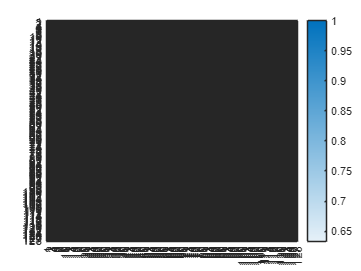

heatmap(Corr_V_dissim)



% % Covariance matrix calculation
% P_L_norm=P_L_demo-P_avg;
%Cov_P_L=cov(P_L_norm)
% Cov_P_L=zeros(Nbus,Nbus);
% for m=1:Nbus
%     for n=1:Nbus
%         S=0;
%         for t=1:T
%             S=S+(P_L_demo(m,t)-P_avg(m,1))*(P_L_demo(n,t)-P_avg(n,1));
%         end
%         Cov_P_L(m,n)=(1/T)*S;
%     end
% end
% size_cov=size(Cov_P_L);
% Cov_P_L_pu=Cov_P_L/1000;

Cov_V_dissim=zeros(Nbus,Nbus);
for m=1:Nbus
    for n=1:Nbus
        S=0;
        for t=1:T
            S=S+(sorted_dissim_voltages(m,t)-V_avg(m,1))*(sorted_dissim_voltages(n,t)-V_avg(n,1));
        end
        Cov_V_dissim(m,n)=(1/T)*S;
    end
end
size_cov=size(Cov_V_dissim);
%heatmap(Cov_V_dissim)

% % Eigen values (D) and vectors (V) of covariance matrix
[V,D]=eig(Cov_V_dissim);

% Sort eigen vectors
non_sortV=V;
colSums = sum(V);
[sumsorted , sortedIndices] = sort(colSums, 'descend');  % Sort indices in descending order
sortedV = V(:, sortedIndices);  % Rearrange columns based on sorted indices
% 
% %%%%%%%%%%%%%%% Online data collection and data recovery %%%%%%%%%%%%%
itrmax=50;
%for itr=1:itrmax
    Ttest=1; % Testing time interval
    L=(Nbus-2)/2 % Total number of data collecting nodes

L = 63

    
    
    % for n=1:Nbus
    %     for t=1:T1
    %         S_L_test(n,t)=testpu(t,n)*T_kw(n,1);
    %     end
    % end
    % figure
    % plot(S_L_test(:,1))
    test_v = xlsread("all_bus_voltages_dissimilar_newest_test.csv")

test_v =        NaN    1.0000    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000   10.0000   11.0000   12.0000   13.0000   14.0000   15.0000   16.0000   17.0000   18.0000   19.0000   20.0000   21.0000   22.0000   23.0000   24.0000   25.0000   26.0000   27.0000   28.0000   29.0000   30.0000   31.0000   32.0000   33.0000   34.0000   35.0000   36.0000   37.0000   38.0000   39.0000   40.0000   41.0000   42.0000   43.0000   44.0000   45.0000   46.0000   47.0000   48.0000   49.0000
         0    1.0495    1.0495    1.0391    1.0391    1.0386    1.0384    1.0382    1.0380    1.0317    1.0267    1.0262    1.0261    1.0260    1.0267    1.0196    1.0262    1.0191    1.0187    1.0189    1.0126    1.0121    1.0118    1.0120    1.0116    1.0116    1.0111    1.0112    1.0110    1.0109    1.0110    1.0109    1.0108    1.0107    1.0105    1.0107    1.0193    1.0104    1.0100    1.0097    1.0098    1.0096    1.0091    1.0089    1.0078    1.0074    1.0069    1.0067    1.0066

    S_L_test = test_v(2:end,2:end)'

S_L_test =     1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495
    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.0495    1.04

    
    
    % UL=sortedV(:,1:L);
    UL=sortedV(:,1);
    S_L=ones(Nbus,1); 
    %S_L = V_avg;% Original power at collected nodes
    % n_L=(randperm(Nbus, L))'; % Index of selected node 
    
    
    % Identify nodes having loads
    k=1;
    for n=1:Nbus
        if T_kw(n,1)~=0
            n_load(k,1)=n;
            k=k+1;
        end
    end
    n_load

n_load =      3
     4
     6
     7
     8
     9
    11
    12
    13
    14


    %indices = find(T_kw ~=0)
    %n_load == indices
    i_L=(randperm(length(n_load), L))'; % Index of selected item from n_load
    
    % Selected Node and their actual measurement
    n_L=zeros(L,1);
    for l=1:L
        n_L(l,1)=n_load(i_L(l,1),1);
    end
    
    for l=1:L
        S_L(n_L(l,1),1,1)=S_L_test(n_L(l,1),1);%-V_avg(n_L(l,1),1);
    end
    S_L = S_L - V_avg;
    % Recovered data
    S_L_rec=V_avg+UL*UL'*S_L;

    % S_L_rec1 = S_L_rec
    % 
    for l=1:L
        S_L_rec(n_L(l,1),1,1)=S_L_test(n_L(l,1),1);
    end
    % 
    % find(S_L_rec1 ~= S_L_rec) == sort(n_L)

    % Integrated normalized absolute error (INAE) and Data Plot
    S_test_tot=zeros(1,T1);
    for t=1:T1
        for n=1:Nbus
            S_test_tot(1,t)=S_test_tot(1,t)+S_L_test(n,t);
        end
    end


    S_rec_tot=0;
    for n=1:Nbus
        S_rec_tot=S_rec_tot+abs(S_L_test(n,Ttest)-S_L_rec(n,1));
    end
    INAE=S_rec_tot/S_test_tot(1,Ttest)

INAE = 6.3565e-04


    % S_rec_tot1=0;
    % for n=1:Nbus
    %     S_rec_tot1=S_rec_tot1+abs(S_L_test(n,Ttest)-S_L_rec1(n,1));
    % end
    % INAE1=S_rec_tot1/S_test_tot(1,Ttest)

    %Error(itr,1)=INAE*100;
%end

figure
T=1:Nbus;
%mplot(T, S_L_test(:,Ttest),T, S_L_rec(:,1))
p=plot(T,[S_L_test(:,Ttest),S_L_rec(:,1)])

p =   2×1 Line array:

  Line
  Line


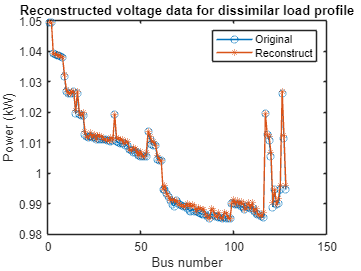

%p=plot(T,[S_L_test(:,Ttest),S_L_rec(:,1)],T,[S_L_test(:,Ttest),S_L_rec1(:,1)])
legend(["Original" "Reconstruct"])
p(1).Marker = 'o';
p(2).Marker = '*';
title('Reconstructed voltage data for dissimilar load profile')
ylabel('Power (kW)')
xlabel('Bus number')

% 


% %Estimating Nodal Power Injections 
% 
% Vbase_LL=4160;
% Pbase_VA=1000000;
% Zbase=(Vbase_LL/sqrt(3))^2/Pbase_VA
% busdata= importdata('bus_data.csv');
% branchdata= importdata('branch_data.csv');
% Bus=busdata.data(:,1);
% Pload=busdata.data(:,2).*1000/Pbase_VA
% Qload=busdata.data(:,3).*1000/Pbase_VA
% nbus=length(Bus);
% 
% fb=branchdata.data(:,1);
% tb=branchdata.data(:,2);
% Rpu=branchdata.data(:,3)/Zbase;
% Xpu=branchdata.data(:,4)/Zbase;
% z=Rpu+1i*Xpu
% nbranch=length(fb);
% ybranch=zeros(nbranch,nbranch);
% for i=1:nbranch
%     ybranch(fb(i),tb(i))=1/z(i);
%     ybranch(tb(i),fb(i))=1/z(i);
% end
% ybranch
% Y=zeros(nbus,nbus);
% for i=1:nbus
%     for j=1:nbus
%         if (i==j)
%             Y(i,j)=Y(i,j);
%             for m=1:nbus
%                 Y(i,j)=Y(i,j)+ybranch(i,m);
%             end
%         else
%             Y(i,j)=-ybranch(i,j);
%         end
%     end
% end
% Y
% g=real(Y)
% b=imag(Y)
% pqv_bus=sort(n_L)
% P_meas = zeros(Nbus,1);
% Q_meas = zeros(Nbus,1);
% Vmag = ones(Nbus,1);
% P_meas(n_L) = testpu(Ttest,n_L(l,1))*Pload(n_L,1);
% Q_meas(n_L) = Qload(n_L);
% Vmag(n_L) = S_L_test(n_L,1);
% reconstructed_nodes = setdiff(bus,n_L);
% Vmag(reconstructed_nodes) = S_L_rec(reconstructed_nodes);
% pqv_buses=pqv_bus'
% n_pqv=length(pqv_buses)
% e_init = ones(nbus,1);
% e_init(1,1) = 1.0495;
% f_init = zeros(nbus,1);
% x0=[e_init;f_init];
% F = @(x) func(x, P_meas, Q_meas, Vmag);
% 
% % Solve the non-linear system
% x = fsolve(F, x0)
% 
% 

% function F = func(x,P_meas,Q_meas,Vmag)
%     global nbus g b n_pqv delta_P delta_Q delta_v% Define global variables
% 
%     e = x(1:nbus);
%     f = x(nbus+1:2*nbus);
%     %Vmag = x(2*nbus+1:3*nbus);
% 
%     P = zeros(n_pqv, 1);%active power injection at pqv buses
%     Q = zeros(n_pqv, 1);%reactive power injection at pqv buses
% 
%     for a = 1:n_pqv
%         i=pqv_buses(a);
%         for k = 1:nbus
%             P(i) = P(i) + e(i) * (g(i, k) * e(k) - b(i, k) * f(k)) + f(i) * (e(k) * b(i, k) + f(k) * g(i, k));
%             Q(i) = Q(i) + f(i) * (g(i, k) * e(k) - b(i, k) * f(k)) - e(i) * (e(k) * b(i, k) + f(k) * g(i, k));
%         end
%         delta_P=P_meas(i)+P(i);%available for only pqv buses
%         delta_Q=Q_meas(i)+Q(i);%available for only pqv buses  
%     end
%     for k = 1:nbus
%         delta_v=e(k).^2 + f(k).^2-Vmag(k).^2;%vmag of all buses will be known
%     end
%     F = [delta_P; delta_Q; delta_v];  
% end


% chatgpt solution
% Estimating Nodal Power Injections 

% Base values and system parameters
Vbase_LL = 4160;             % Base line-to-line voltage in volts
Pbase_VA = 1000000;          % Base power in VA
Zbase = (Vbase_LL / sqrt(3))^2 / Pbase_VA;  % Base impedance

% Import data
busdata = importdata('bus_data.csv');
branchdata = importdata('branch_data.csv');

% Bus data
Bus = busdata.data(:,1);
Pload = busdata.data(:,2) .* 1000 / Pbase_VA;  % Convert to per unit
Qload = busdata.data(:,3) .* 1000 / Pbase_VA;  % Convert to per unit
nbus = length(Bus);

% Branch data
fb = branchdata.data(:,1);  % From bus
tb = branchdata.data(:,2);  % To bus
Rpu = branchdata.data(:,3) / Zbase;  % Resistance in per unit
Xpu = branchdata.data(:,4) / Zbase;  % Reactance in per unit
z = Rpu + 1i * Xpu;  % Impedance in per unit
nbranch = length(fb);

% % Admittance matrix calculation
% ybranch = zeros(nbus, nbus);
% for i = 1:nbranch
%     ybranch(fb(i), tb(i)) = 1 / z(i);
%     ybranch(tb(i), fb(i)) = 1 / z(i);
% end
% 
% Y = zeros(nbus, nbus);  % Initialize Y-bus (admittance) matrix
% for i = 1:nbus
%     for j = 1:nbus
%         if i == j
%             Y(i,j) = sum(ybranch(i, :));  % Sum of all admittances connected to bus i
%         else
%             Y(i,j) = -ybranch(i,j);  % Off-diagonal elements are negative admittances
%         end
%     end
% end

ybranch=zeros(nbranch,nbranch);
for i=1:nbranch
    ybranch(fb(i),tb(i))=1/z(i);
    ybranch(tb(i),fb(i))=1/z(i);
end
ybranch

ybranch = 1.0e+06 *

   0.0000 + 0.0000i   2.8843 - 2.8843i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   2.8843 - 2.8843i   0.0000

Y=zeros(nbus,nbus);
for i=1:nbus
    for j=1:nbus
        if (i==j)
            %Y(i,j)=Y(i,j);
            for m=1:nbus
                Y(i,j)=Y(i,j)+ybranch(i,m);
            end
        else
            Y(i,j)=-ybranch(i,j);
        end
    end
end

% Separate real and imaginary parts of the Y-bus matrix
g = real(Y);  % Conductance matrix
b = imag(Y);  % Susceptance matrix

% Assuming n_L is a vector with indices of load buses and testpu is defined
pqv_bus = sort(n_L);  % Sort the load buses
P_meas = zeros(nbus, 1);
Q_meas = zeros(nbus, 1);
Vmag = ones(nbus, 1);  % Initial guess for voltage magnitudes

% Assign measured power values to the appropriate buses
P_meas(n_L) = testpu(Ttest,n_L(l,1))*Pload(n_L,1);  % Active power at load buses
Q_meas(n_L) = Qload(n_L);  % Reactive power at load buses
Vmag(n_L) = S_L_test(n_L, 1);  % Initial voltage magnitudes at load buses

% Handle reconstructed nodes (if applicable)
reconstructed_nodes = setdiff(Bus, n_L);
Vmag(reconstructed_nodes) = S_L_rec(reconstructed_nodes);  % Initial guess for voltage at reconstructed nodes

% Define the buses where we want to calculate the power (pqv buses)
pqv_buses = pqv_bus';
n_pqv = length(pqv_buses);

% Initial guess for state variables (voltage components)
e_init = ones(nbus, 1);  % Initial guess for real part of voltage
e_init(1) = 1.0495;  % Assuming the reference bus voltage magnitude is 1.0495 p.u.
f_init = zeros(nbus, 1);  % Initial guess for imaginary part of voltage
x0 = [e_init; f_init];  % Combine initial guesses into one vector

% Define global variables for use in the function
global nbus g b n_pqv pqv_buses;


% Define the function handle with additional arguments
F = @(x) power_flow_equations(x, P_meas, Q_meas, Vmag);

% Solve the non-linear system of equations using fsolve
options = optimoptions('fsolve', 'Display', 'iter', 'TolFun', 1e-9, 'TolX', 1e-9);
x = fsolve(F, x0, options);


                                        First-order                     Norm of 
 Iteration  Func-count   ||f(x)||^2      optimality       Lambda           step
     0         257         0.174243        6.35e+04         0.01
     1         514       0.00118702         1.1e+04        0.001       0.188065
     2         771       0.00109689        6.75e+03       0.0001      0.0798576
     3        1030       0.00104895         3.8e+03         0.01      0.0371878
     4        1287      0.000996703        3.52e+03        0.001      0.0463553
     5        1545      0.000925757        3.52e+03         0.01      0.0533906
     6        1802      0.000849748        2.19e+03        0.001      0.0541072
     7        2059      0.000787065        2.35e+03       0.0001       0.133489
     8        2317      0.000715788        1.13e+03        0.001      0.0804177
     9        2574       0.00069785            86.4       0.0001      0.0662434
    10        2832      0.000684135             467  


% Extract the solved voltage components
e = x(1:nbus)

e =     1.0495
    1.0495
    1.0391
    1.0391
    1.0380
    1.0387
    1.0384
    1.0387
    1.0322
    1.0270


f = x(nbus+1:2*nbus)

f =    -0.0000
   -0.0024
   -0.0018
   -0.0017
    0.0030
    0.0000
    0.0032
    0.0033
   -0.0032
   -0.0001



% Calculate the voltage magnitudes and angles
Vmag_final = sqrt(e.^2 + f.^2);
Vangle_final = atan2(f, e);

% Display results
disp('Voltage magnitudes (p.u.):');

Voltage magnitudes (p.u.):


disp(Vmag_final);

    1.0495
    1.0495
    1.0391
    1.0391
    1.0380
    1.0387
    1.0384
    1.0387
    1.0322
    1.0270
    1.0266
    1.0266
    1.0267
    1.0271
    1.0201
    1.0265
    1.0192
    1.0196
    1.0199
    1.0122
    1.0127
    1.0130
    1.0121
    1.0126
    1.0117
    1.0122
    1.0123
    1.0122
    1.0113
    1.0113
    1.0106
    1.0110
    1.0116
    1.0118
    1.0107
    1.0193
    1.0116
    1.0112
    1.0110
    1.0102
    1.0105
    1.0104
    1.0102
    1.0075
    1.0077
    1.0083
    1.0073
    1.0075
    1.0059
    1.0071
    1.0053
    1.0055
    1.0067
    1.0138
    1.0120
    1.0104
    1.0097
    1.0097
    1.0044
    1.0048
    1.0049
    0.9947
    0.9953
    0.9931
    0.9922
    0.9912
    0.9911
    0.9909
    0.9854
    0.9881
    0.9909
    0.9924
    0.9926
    0.9892
    0.9900
    0.9893
    0.9890
    0.9896
    0.9890
    0.9873
    0.9888
    0.9883
    0.9818
    0.9872
    0.9873
    0.9870
    0.9902
    0.9884
    0.9866
    0.9868
    0.9857

disp('Voltage angles (radians):');

Voltage angles (radians):


disp(Vangle_final);

   -0.0000
   -0.0023
   -0.0017
   -0.0017
    0.0029
    0.0000
    0.0031
    0.0031
   -0.0031
   -0.0001
    0.0001
    0.0000
    0.0000
   -0.0001
    0.0434
   -0.0000
   -0.0119
   -0.0117
    0.0000
   -0.0644
   -0.0642
   -0.0641
   -0.0001
    0.0001
   -0.0001
    0.0001
    0.0568
    0.0519
   -0.0000
    0.0350
    0.0023
   -0.0361
    0.0000
   -0.0572
    0.0052
    0.0102
    0.2564
    0.0000
    0.0000
   -0.0001
    0.0001
    0.0813
    0.0000
    0.0157
    0.0158
   -0.0370
   -0.0000
    0.0000
    0.0126
    0.0610
   -0.0187
   -0.0500
   -0.0813
   -0.0209
   -0.0534
    0.0000
   -0.0000
    0.0000
   -0.1905
   -0.1904
   -0.1903
    0.2894
   -0.4508
    0.2660
    0.2496
    0.2167
    0.1767
   -0.0000
    0.0131
    0.0138
    0.0146
    0.0150
    0.0151
   -0.0704
   -0.1419
   -0.0000
   -0.0000
   -0.1125
    0.0598
    0.0166
   -0.0692
   -0.0071
   -0.0007
   -0.0000
    0.0000
    0.0006
    0.0014
   -0.0000
    0.0556
    0.0557
    0.0187


    P = zeros(nbus, 1);
    Q = zeros(nbus, 1);

    % Calculate P and Q for each bus
    for i = 1:nbus
        for k = 1:nbus
            P(i) = P(i) + e(i) * (g(i, k) * e(k) - b(i, k) * f(k)) + f(i) * (e(k) * b(i, k) + f(k) * g(i, k));
            Q(i) = Q(i) + f(i) * (g(i, k) * e(k) - b(i, k) * f(k)) - e(i) * (e(k) * b(i, k) + f(k) * g(i, k));
        end
    end
    P

P = 1.0e+06 *

    0.0074
   -0.0074
    0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000


    Q

Q = 1.0e+06 *

   -0.0074
    0.0074
    0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


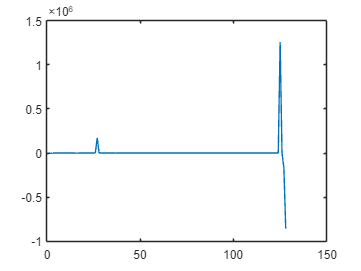

    plot(1:128,P)

function F = power_flow_equations(x, P_meas, Q_meas, Vmag)
    global nbus g b n_pqv pqv_buses;

    e = x(1:nbus);  % Real part of voltages
    f = x(nbus+1:2*nbus);  % Imaginary part of voltages

    % Initialize active and reactive power injections
    P = zeros(nbus, 1);
    Q = zeros(nbus, 1);

    % Calculate P and Q for each bus
    for i = 1:nbus
        for k = 1:nbus
            P(i) = P(i) + e(i) * (g(i, k) * e(k) - b(i, k) * f(k)) + f(i) * (e(k) * b(i, k) + f(k) * g(i, k));
            Q(i) = Q(i) + f(i) * (g(i, k) * e(k) - b(i, k) * f(k)) - e(i) * (e(k) * b(i, k) + f(k) * g(i, k));
        end
    end

    % Calculate mismatches for PQ buses
    delta_P = zeros(n_pqv, 1);
    delta_Q = zeros(n_pqv, 1);
    for a = 1:n_pqv
        i = pqv_buses(a);
        delta_P(a) = P_meas(i) - P(i);  % Active power mismatch
        delta_Q(a) = Q_meas(i) - Q(i);  % Reactive power mismatch
    end

    % Voltage magnitude mismatch for all buses
    delta_v = zeros(nbus, 1);
    for k = 1:nbus
        delta_v(k) = e(k).^2 + f(k).^2 - Vmag(k).^2;
    end

    % Combine all mismatches into one vector
    F = [delta_P; delta_Q; delta_v];  
end
